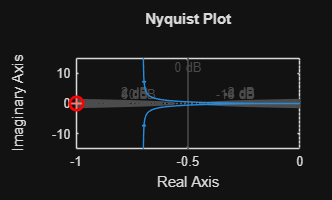

clc
clear
close all

s = tf('s');

% Open loop transfer function
G = 10/(s*(s+2)*(s+5));

% Nyquist Plot
figure
nyquist(G)
grid on
hold on
plot(-1,0,'ro','MarkerSize',10,'LineWidth',2)
title('Nyquist Plot')

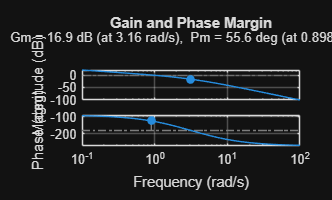


% Gain and Phase Margin
figure
margin(G)
grid on
title('Gain and Phase Margin')


% Closed Loop System
T = feedback(G,1);

disp('Closed Loop Poles:')

Closed Loop Poles:


pole(T)

ans =   -5.5157 + 0.0000i
  -0.7422 + 1.1235i
  -0.7422 - 1.1235i
